close all;
clear all;
Data=xlsread('cross_section_influence_1.csv');
c=1;
for i=1:length(Data)
    a1=Data(i,1);
    if ~isnan(a1)
        ini_index(c)=i+2;
        c=c+1;
        i=i+1;
    else
        i=i+1;
    end
end
a=1; 
b=ones(1,8)./8;
ll=length(ini_index);
for i=1:ll
    if i<ll
        A{i}=Data(ini_index(i)-2:ini_index(i+1)-3,:);
    else
        A{i}=Data(ini_index(i)-2:end,:);
    end
end
st=1;
ed=5;
int=5;


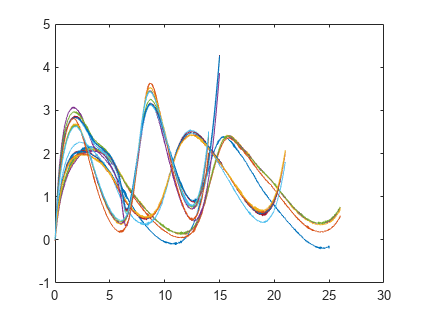


% All figures
for j=1:ll
    if j<ll
        x1=Data(ini_index(j):ini_index(j+1)-3,4);
        y1= filter(b,a,x1);
        d1=Data(ini_index(j):ini_index(j+1)-3,3);
        plot(d1,y1);
        hold on
    else
        x1=Data(ini_index(j):end,4);
        y1= filter(b,a,x1);
        d1=Data(ini_index(j):end,3);
        plot(d1,y1);
        hold on
    end
end


%%simplified figure
figure('DefaultAxesFontSize',17,'Position',[50 50 600 480])
color.code=colormap(slanCM(160));

@author : slandarer


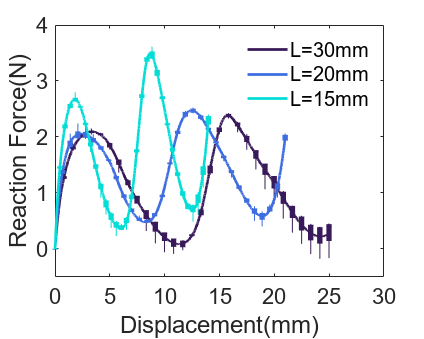

color.l=length(color.code);
color.index1=round(color.l*2/9);
color.index2=round(color.l*5/9);
color.index3=round(color.l*8/9);
%newcolors={'#CD84F1', '#FFCCCC', '#FF4D4D', '#FFAF40', '#2F3542', '#FFFA65'};
%newcolors2=hex2rgb(newcolors);
%colororder(newcolors2);
[yave1,dave1,Y1,pos1]=data_ave_and_bocplot([A{1};A{2};A{3};A{4};A{5}]);
[yave2,dave2,Y2,pos2]=data_ave_and_bocplot([A{6};A{7};A{8};A{9};A{10}]);
[yave3,dave3,Y3,pos3]=data_ave_and_bocplot([A{11};A{12};A{13};A{14};A{15}]);
[yave4,dave4,Y4,pos4]=data_ave_and_bocplot([A{16};A{17};A{18};A{19};A{20}]);
plot(dave1,yave1,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y1,'Positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
plot(dave2,yave2,'Color',color.code(color.index2,:),'LineWidth',2);
hold on
boxplot(Y2,'Positions',pos2,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
plot(dave4,yave4,'Color',color.code(color.index3,:),'LineWidth',2);
hold on
boxplot(Y4,'Positions',pos4,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
axis([0 30 -0.5 4]);
xticks([0:5:30]);
xticklabels({'0','5','10','15','20','25','30'});

legend('L=30mm','L=20mm','L=15mm');
legend('Boxoff')
legend('FontName','Arial')
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
ax=gca;
ax.FontName='Arial';

%title('Effects of cross-section area on stiffness & frequency variation, t_t_p_u=0.68mm');